% scanimage computer
stim_dir = 'F:\Users\juyoung\mystim';
data_dir = 'F:\Users\juyoung\data\1107';
matlab_dir = 'C:\Users\scanimage\Documents\MATLAB\Matlab_juyoung';

% My macbook pro 2012
stim_dir = ' ';
data_dir = '/Users/peterfish/Documents/1__Retina_Study/DATA_2016/16-10-31';
matlab_dir = '/Users/peterfish/Documents/Matlab-lib';

## Update and upload the library  

% Add an update, commit and push
cd(matlab_dir);             
commitStr = sprintf('Library update on %s', datestr(now));
evalc(['!git add -A; git commit -am "' commitStr '"; git push;']);

## Get PD signal for the first time

% struct g after sorting
% spikes from i-th file (experiment) and align the timestamps of 'all' cells relative to events.
% PD should provide timings of the events.
cd(data_dir);
%
[pd, ev_id, srate] = getpd('1031drift.h5');
save('pd.mat', 'pd');
load('16-10-31.mat');

## Get 'ex' struct

str_exper = '16-11-07';
str_today = datestr(now, 'yy-mm-dd');
% up-to-date visual stimulus
cd(stim_dir);
!git pull

Permission denied (publickey). 
fatal: Could not read from remote repository.

Please make sure you have the correct access rights
and the repository exists.


% load 'ex' struct
basedir = fullfile('logs/', str_exper);
ex_file = fullfile(basedir,'exlog.mat');
load(ex_file);

## Load 'g' (sorted spikes) and 'pd'. Detect trigger events

cd(data_dir);
if ~exist('g')
    load('16-11-07.mat');
end
if ~exist('pd')
    load('pd.mat');
end
% load ex struct
params = ex.stim{1}.params;
% Duration of repeat (one experiment)
ifi = ex.disp.ifi;
numframes = params.jumpevery;
n_session = params.n_session;
s_duration = numframes * ifi

s_duration = 1.4119

repeat_duration = n_session * s_duration

repeat_duration = 16.9425

% event timeedges
min_interval_secs = 5*s_duration;
ev_secs = pd_event_display(pd, min_interval_secs, 0.7);

## Stimulus for RF mapping

cd(stim_dir);
% check if recreation is 'yes'
[ex, noise_stim] = rf_noise(ex, 'recreation', 'yes',  ...           
            'movieDurationSecs', (60*30), ... % 30 min
            'checkerSizeXum', 50, ...
            'checkerSizeYum', 50, ...
              'stimSizeXYum', 3500*[1 1]);

## STA analysis of sorted cells

% sorted cell list
s = list_sorted_cells(g);
% file list
s(1)

ans =              files: {'1107obj.h5'  '1107rf.h5'}
    N_sorted_cells: 13
               CHs: [14 18 20 23 24 25 28 30 32 41 47 48]
             times: {[1×13206 double]  [1×797 double]}
                ch: 14


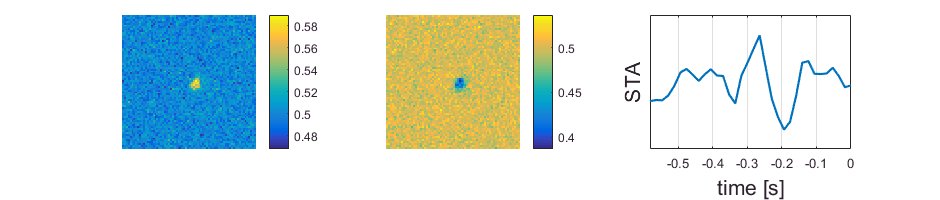

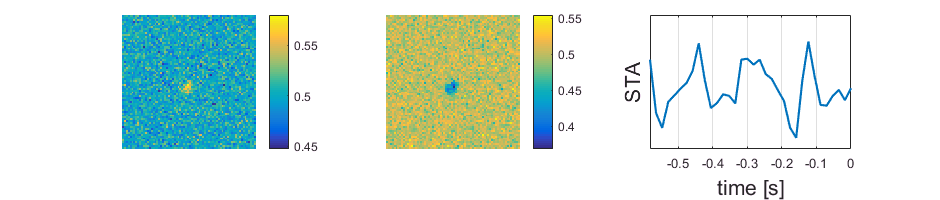

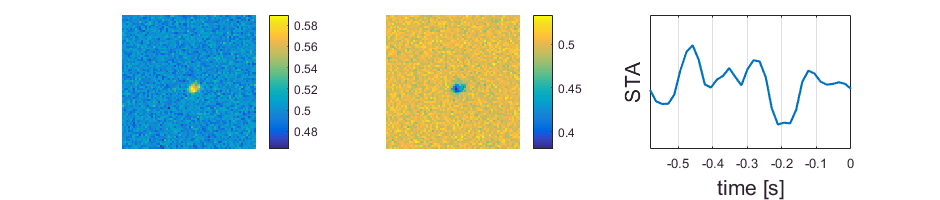

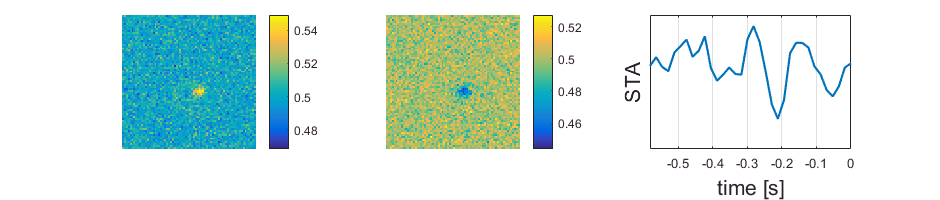

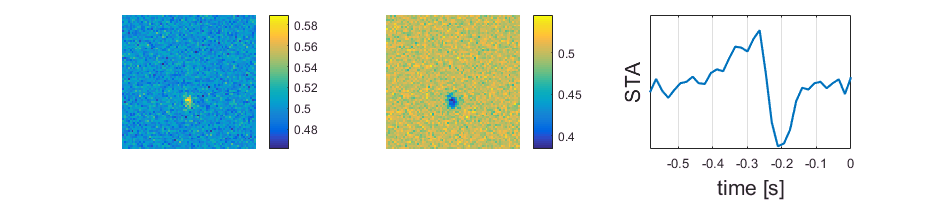

i_rf_file = 2;
%
srate = 10000;
upsampling = 2;
STA_period = 0.6;
%
j_cell = 6:10;
for j = j_cell
    rf = STA(s(j).times{i_rf_file}/srate, STA_period, noise_stim, upsampling, 3*ex.disp.ifi);
end

## Spike timestamps of j-th cell and Align relative to trigger events (PD)

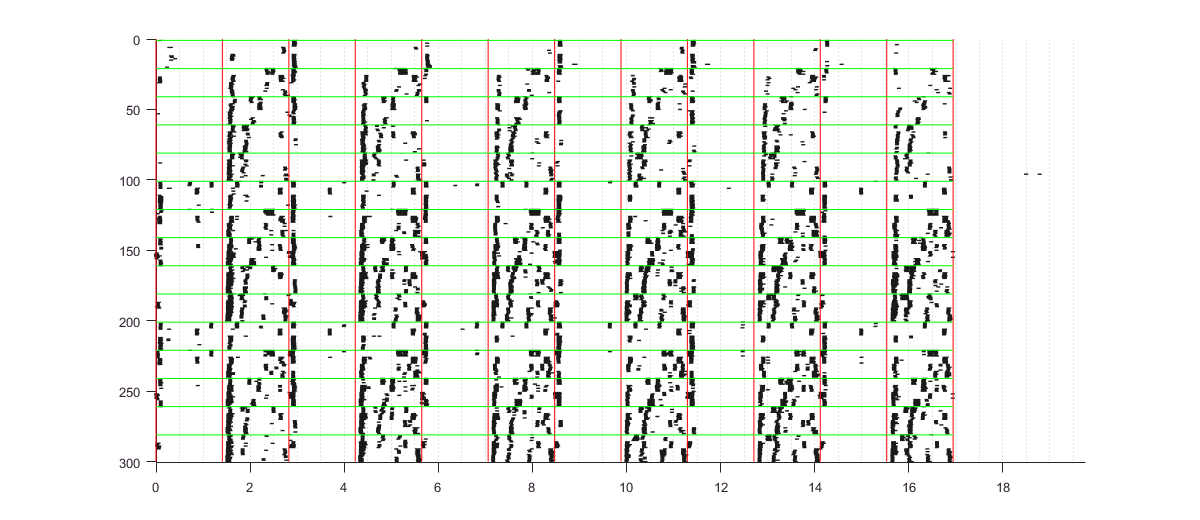

j_cell = 7; % cell id

% Align spikes of a specific experiment (filename) relative to PD trigger events
i_file = 1; % file id (experiment id)
all_spikes = align_sorted_cells(s, ev_secs, i_file);

% adjust abnormal lines (array): all cell
abnormal_lines = [97];
t_shift_needed = [2*s_duration];
all_spikes = shifttime(all_spikes, abnormal_lines, t_shift_needed);

% display
figure; 
H_line_every = params.n_jitter*params.n_repeat; % speed scan
V_lines = (0:n_session) * s_duration;
myraster(all_spikes{j_cell}, H_line_every, V_lines); 
xlim([0, repeat_duration + 2*s_duration]);

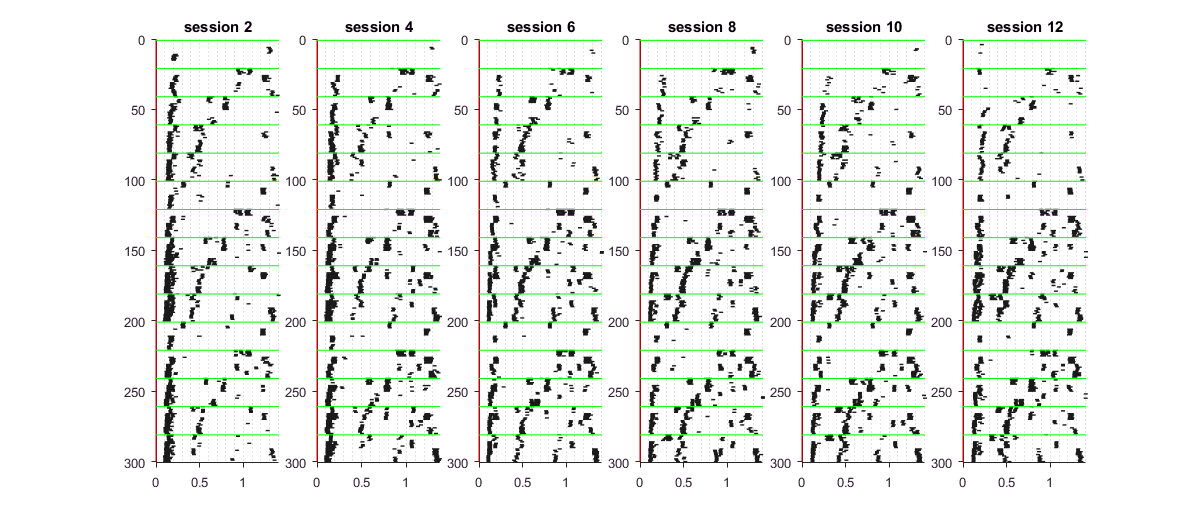

% Align (split) spikes relative to sessions
ev_session = 0:s_duration:s_duration*(n_session-1);
spikes_splited = split_to_event(all_spikes{j_cell}, ev_session);

% Focus on transitions
s_id = [2, 4, 6, 8, 10, 12]; % session ids of transitions
n_transitions = length(s_id);
rate = cell(1, n_transitions);
figure;
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    s_spikes = spikes_splited{s_id(i)}; % Use simpler name
    myraster(s_spikes, H_line_every, [0, s_duration]); title(['session ',num2str(s_id(i))]); xlabel('[secs]');
    % calcuate rate
    bin_size = 0.01;
    smoothing = 3;
    rate{i} = ts_rate_cell(s_spikes, [0 s_duration], bin_size, smoothing); % rate is an array
end

## Plot firing rate

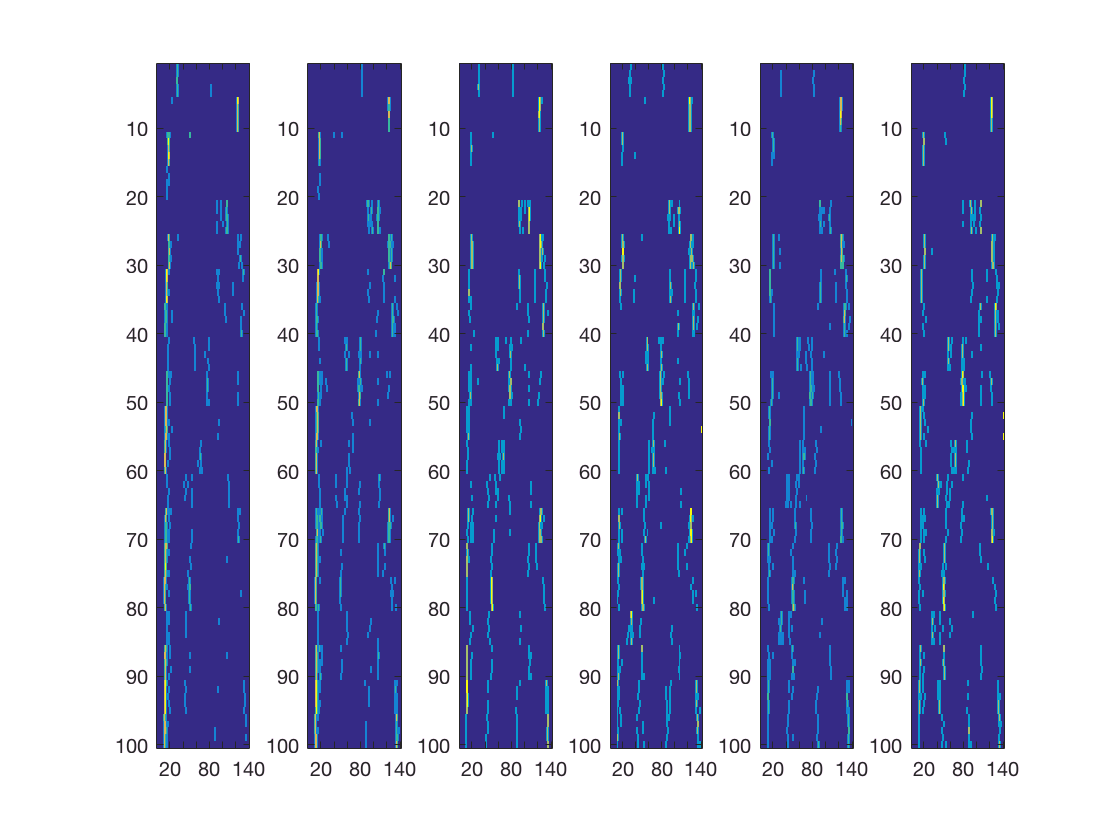

n_condition = 3;
c_range = cell(n_condition, 1);
%
% interevent(i) = pd(i+1)-pd(i);


%


% line (experiment) range
i_exp = 201; % line id for experiment
n_exp = 100;    % # of lines
trigger_missing = 1;
i_exp = i_exp - trigger_missing;
%

%
figure; 
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    imagesc(rate{i}(i_exp:i_exp+n_exp-1,:));
end

## Close up 'k-th' session for choosing appropriate time window 

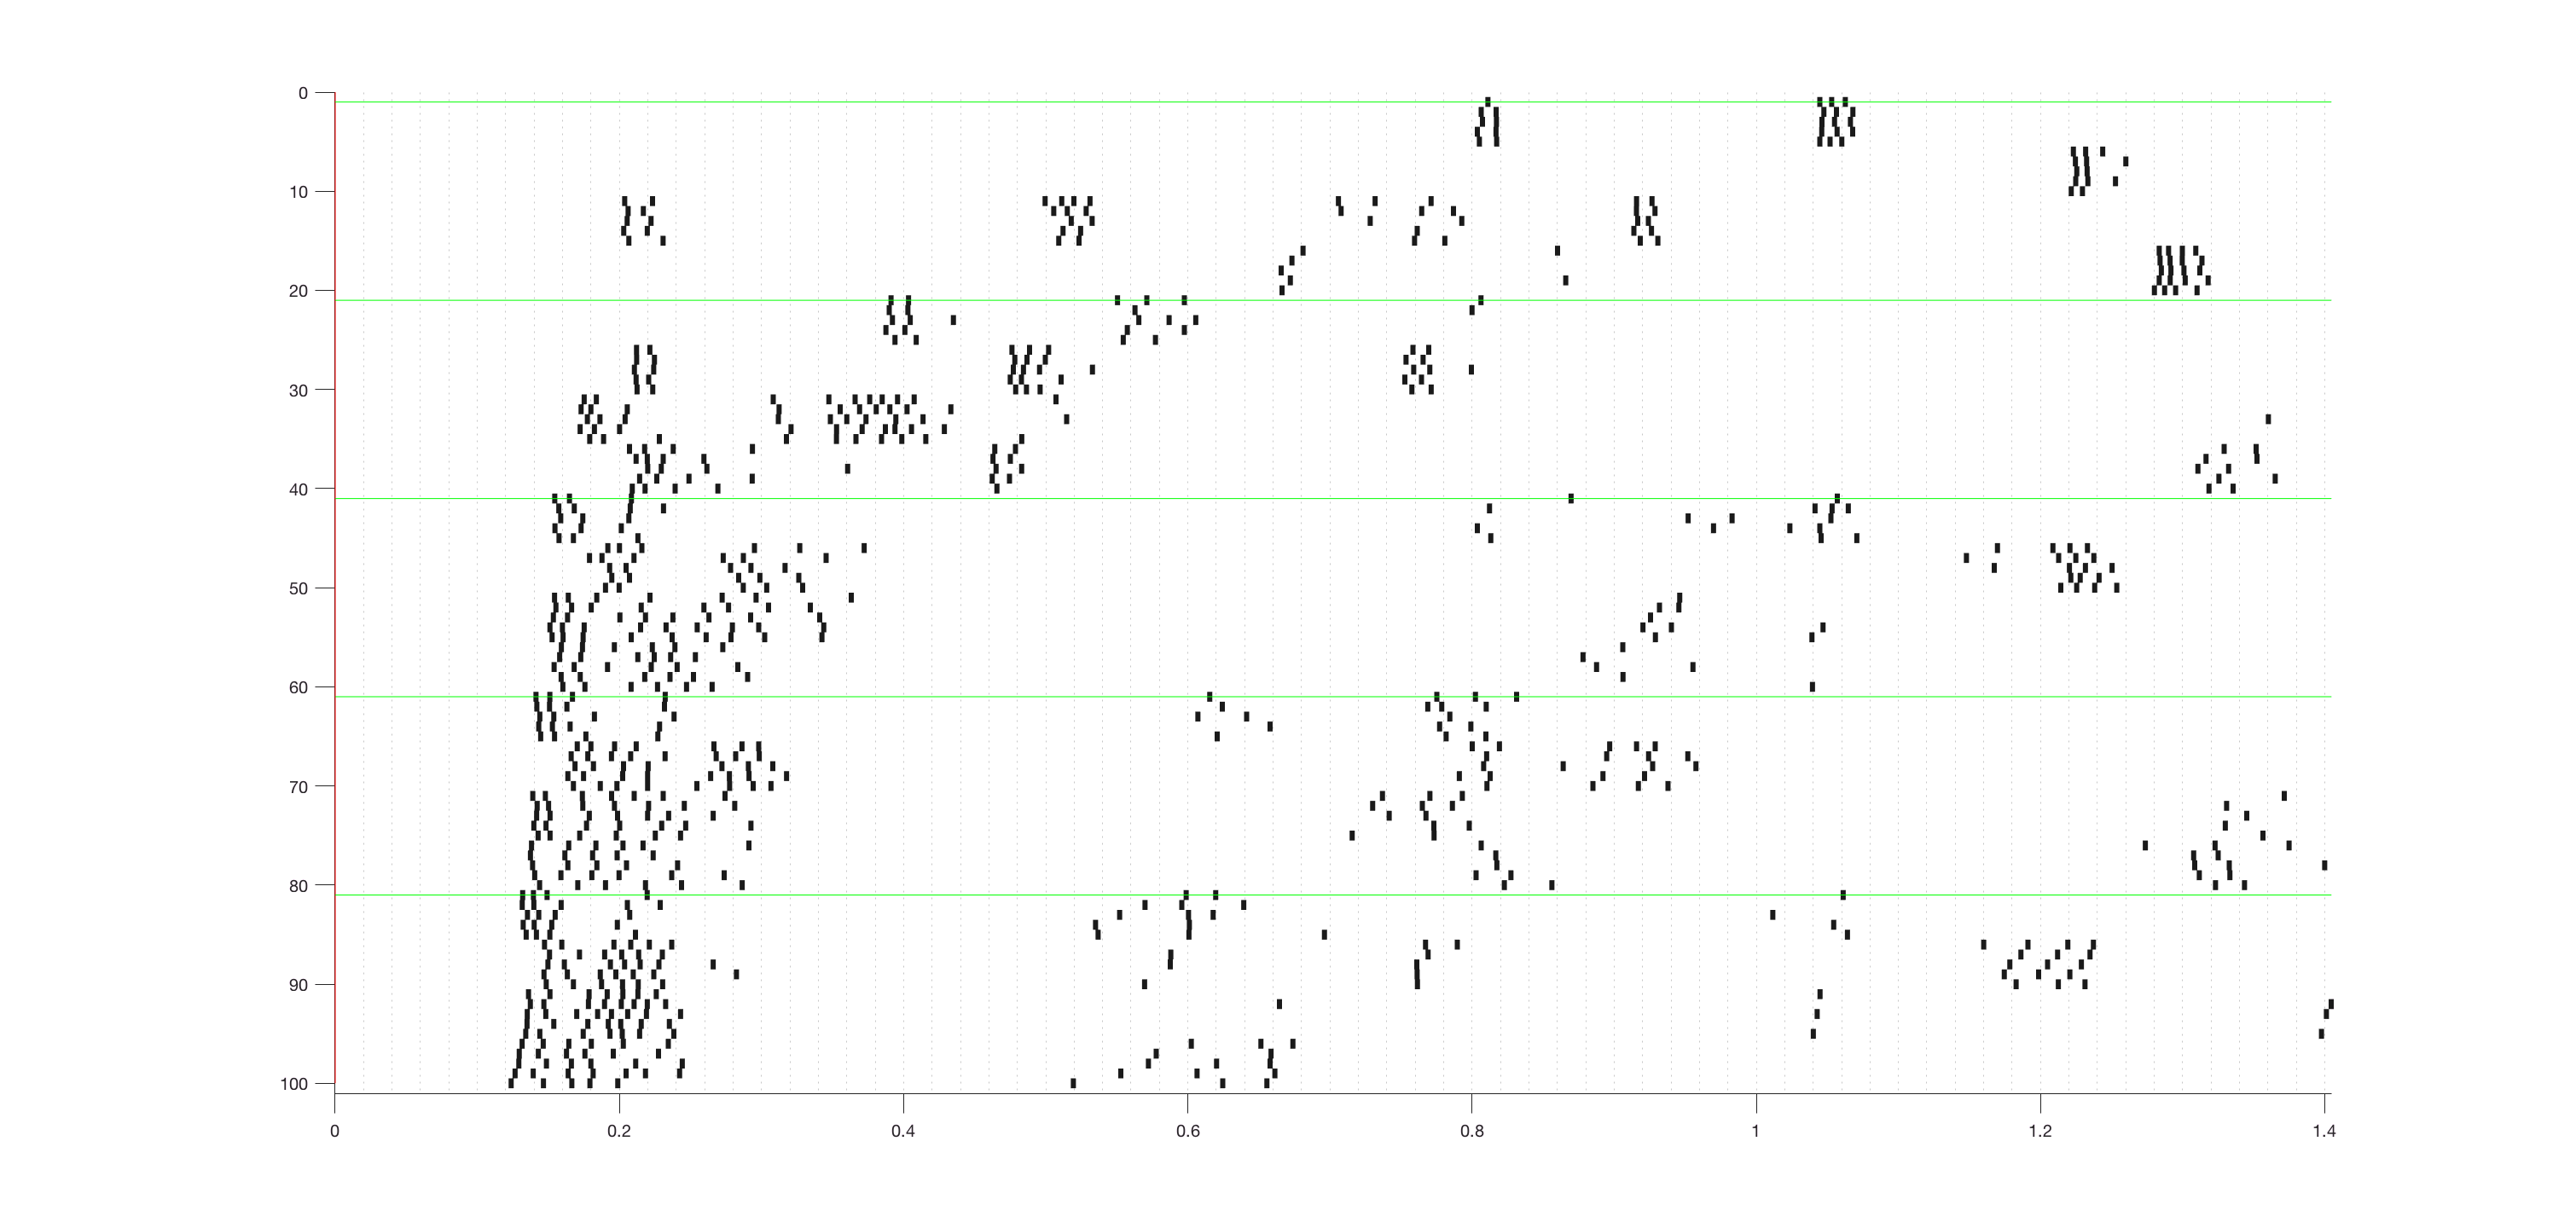

k_session = n_session;
s_spikes = spikes_splited{k_session}(i_exp:i_exp+n_exp-1);
figure; myraster(s_spikes, H_line_every);

## Analysis with 'Firing Rate':

Avg & STD over identical repeats

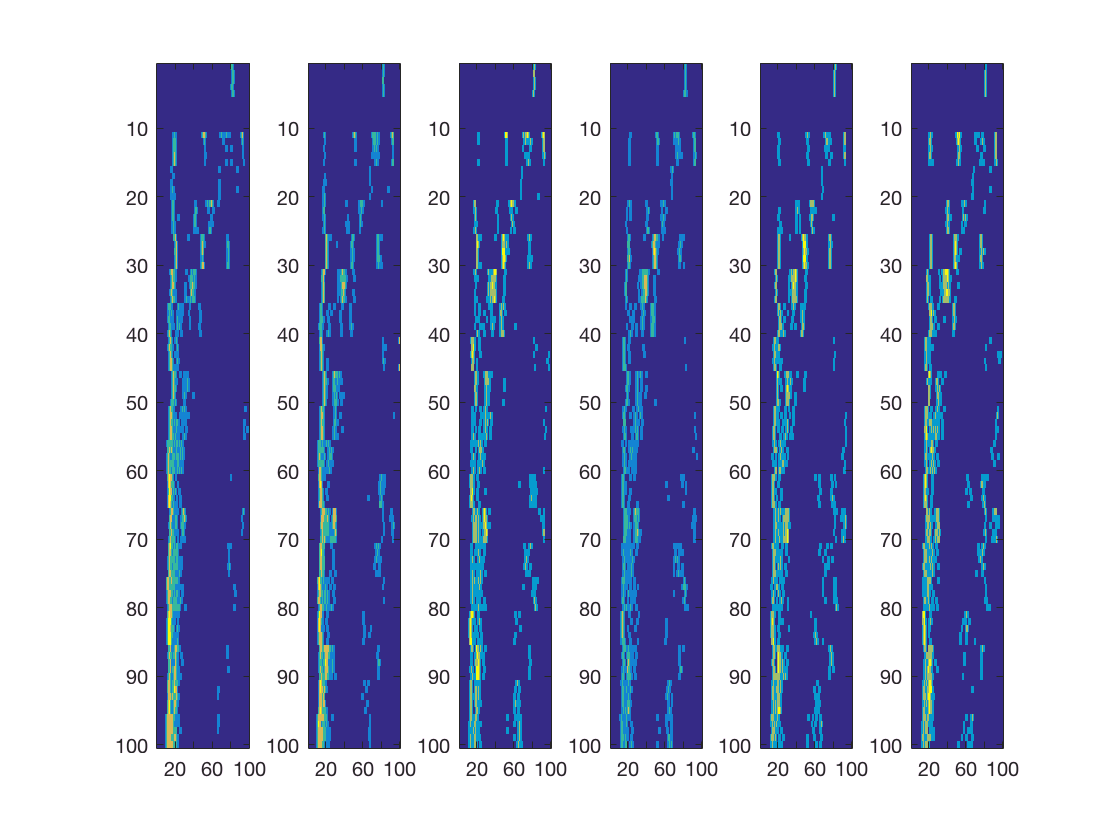

t_window = [0, 1.0];
%t_window = [0 duration];
t_duration = t_window(2)-t_window(1);
% timestamps to firing rate (basically, binning & smoothing)
bin_size = 0.01;
smoothing = 3;
%
figure; title(['time window']);
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    s_spikes = spikes_splited{s_id(i)}(i_exp:i_exp+n_exp-1,:);
    rate{i} = ts_rate_cell(s_spikes, t_window, bin_size, smoothing); % rate is an array
    imagesc(rate{i});
    ax = gca;
    ax.DataAspectRatioMode = 'auto';
    ax.PlotBoxAspectRatioMode = 'auto';
    ax.CameraViewAngleMode = 'auto';
end

S = sprintf('drift %d*', 1:n_transition); C = regexp(S, '*', 'split');

Undefined function or variable 'n_transition'.


D = regexp(S, '*', 'split');
legend(D{1:(end-1)});

[rate_avg, rate_std] = stat_every_all(    rate, n_repeat);
[rate_avg, rate_std] = stat_every_all(rate_avg, n_jitter);

[mean_r, peak_r, peak_t, first_t] = rate_analysis_all(rate_avg, bin_size);

## Tuning curves with different exp conditions (e.g. speed)

figure; hold on;
cellfun(@plot, peak_r);  
ylabel('Hz');